Initiate

close all
clearvars
clc
if ~exist('../Figures', 'dir')
    mkdir('../Figures')
end
cd ../results/

Load data files

load('dxyz.dat',             '-ascii');
load('Nxyz.dat',             '-ascii');
load('InitPoint.dat',        '-ascii');
rho.data = load('rhoAmb.dat',           '-ascii');
Links.ID = load('EstablishedLinks.dat', '-ascii');
gnd.alt  = load('z_gnd.dat',            '-ascii');

Derive main parameters

Links.Nb = size(Links.ID);
Links.Nb = Links.Nb(1);
N.x = Nxyz(1);
N.y = Nxyz(2);
N.z = Nxyz(3);

d.x = dxyz(1);           % _m
d.y = dxyz(2);           % _m
d.z = dxyz(3);           % _m

L.x = (N.x-1)*d.x;         % _m
L.y = (N.y-1)*d.y;         % _m
L.z = (N.z-1)*d.z;         % _m

S.x = InitPoint(1);   % _m
S.y = InitPoint(2);   % _m
S.z = InitPoint(3);   % _m
S.R = InitPoint(4);   % _m

S.i = round(S.x/d.x);
S.j = round(S.y/d.y);
S.k = round(S.z/d.z);

rho.data = ConvertTo3d(rho.data,Nxyz); % _C/_m^3

clear Nxyz
clear dxyz
clear InitPoint


x = ((0:(N.x-1))*d.x)*1e-3;
y = ((0:(N.y-1))*d.y)*1e-3;
z = ((0:(N.z-1))*d.z + gnd.alt)*1e-3;

[X,Y,Z]=meshgrid(x,y,z);
rho.max = .95* max(max(max(rho.data)));
rho.min = .95* min(min(min(rho.data)));

Map ColorScale

gnd.color = [.75 .75 .75];%[.718 .255 .055];
color     = colormap(jet(Links.Nb));
is.BW = 1;%input('Is plot Monochrome? (1: yes, else: no)\n>> ');
if (is.BW == 1)
    for ii=1:Links.Nb
        color(ii,:) = [0 0 1];
    end
end

Set movie recording

is.Rec = 1; % input('Record the movie? (1: yes, else: no)\n>> ');
if (is.Rec == 1)
    Movie = VideoWriter('../Figures/lightning','MPEG-4');
    open(Movie);
end

Draw the tree

figure(1);

set(gcf,'Units','inches','OuterPosition', [20 20 20 20]/3,'Color','white')
hold

Current plot held


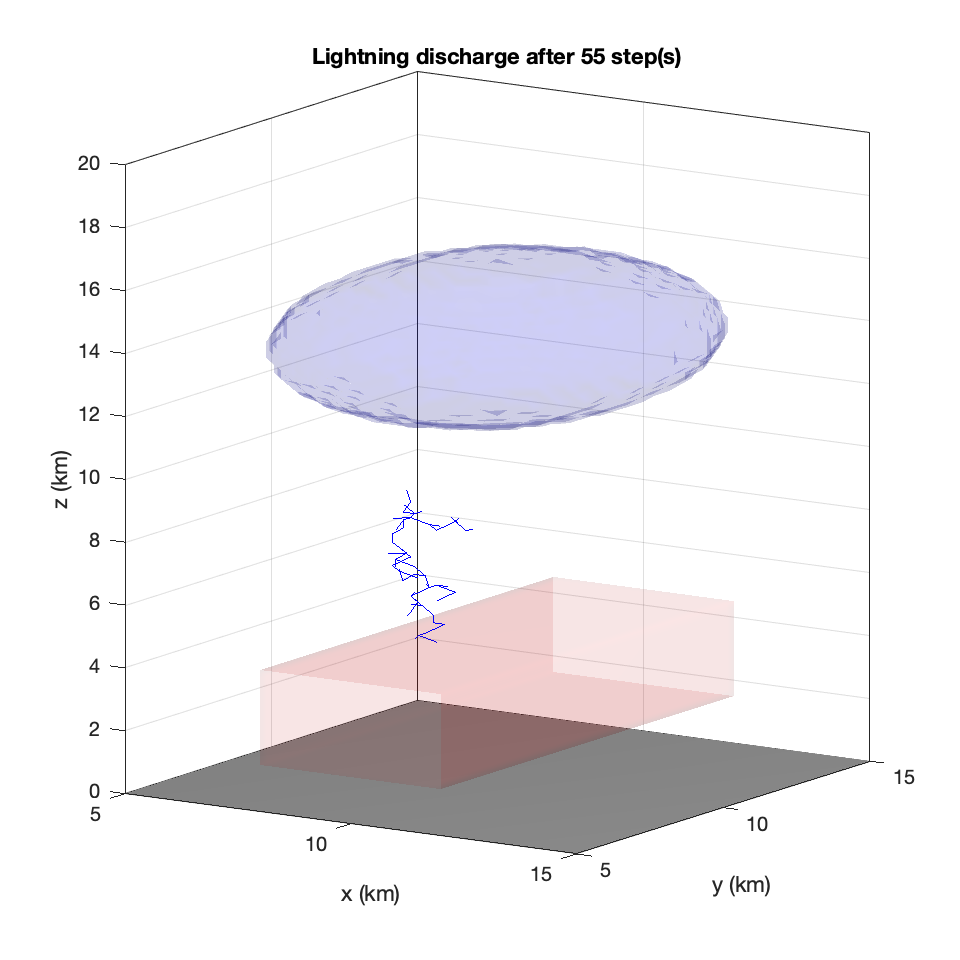

%Cloud3D(3e3, 18e3, L.x, L.y, L.z, gnd.alt);

P.x = [L.x 0 0 L.x]*1e-3;
P.y = [L.y L.y 0 0]*1e-3;
P.z = [gnd.alt gnd.alt gnd.alt gnd.alt]*1e-3;
patch(P.x, P.y, P.z, gnd.alt,'FaceColor',gnd.color);

% xc = S.x;
% yc = S.y;
% zc = S.z;
% L.x = 4*d.x;%0.0025;%2e-3;
% L.y = 4*d.y;%0.0025;%2e-3;
% L.z = 4*d.z;%0.0025;%2e-3;

% [X,Y,Z] = sphere(20);
% X = S.R*X + S.x*ones(size(X));
% Y = S.R*Y + S.y*ones(size(Y));
% Z = S.R*Z + S.z*ones(size(Z));
% % surf(X,Y,Z)
% mesh(X,Y,Z)

for ii=1:Links.Nb
    %     if(rem(ii,10)==0)
    %         %         pause;
    %     end
    
    plot3(...
        [Links.ID(ii,1)*d.x      , Links.ID(ii,4)*d.x      ]*1e-3,...
        [Links.ID(ii,2)*d.y      , Links.ID(ii,5)*d.y      ]*1e-3,...
        [Links.ID(ii,3)*d.z+gnd.alt, Links.ID(ii,6)*d.z+gnd.alt]*1e-3,...
        'Color',color(ii,:));
    axis([L.x*1/4 L.x*3/4 L.y*1/4 L.y*3/4 gnd.alt 2/2*(L.z+gnd.alt)]*1e-3)
    %     axis equal
    box on
    xlabel('x (km)','FontSize',12);
    ylabel('y (km)','FontSize',12);
    zlabel('z (km)','FontSize',12);
    title(['Lightning discharge after ', int2str(ii) ,' step(s)'],'FontSize',12,'FontWeight','bold');
    set(gca,'FontSize',10);
    view([33 10])
    frame = getframe(gcf);
    if(is.Rec == 1)
        writeVideo(Movie,frame);
    end
end

% figure(1)
p1 = patch(isosurface(X,Y,Z,rho.data,rho.max));
isonormals(x,y,z,rho.data,p1);
set(p1,'FaceColor','red','EdgeColor','none','FaceAlpha',0.1); % set the color, mesh and transparency level of the surface


p2 = patch(isosurface(x,y,z,rho.data,rho.min));
isonormals(x,y,z,rho.data,p2);
set(p2,'FaceColor','blue','EdgeColor','none','FaceAlpha',0.1);
view([33 10])

% daspect([1,1,1])
% view(3);
camlight; lighting gouraud
axis([L.x*1/4 L.x*3/4 L.y*1/4 L.y*3/4 gnd.alt 2/2*(L.z+gnd.alt)]*1e-3)
view([33 10])
% ax = gca;
grid on


frame = getframe(gcf);
hold off;

Record the movie

if (is.Rec == 1)
    writeVideo(Movie,frame);
    close(Movie);
end

Go back to initial folder

cd ../viz

function [AA] = ConvertTo3d(A,B)
[M, N] = size(A);
AA = zeros(B');
for m=1:M
    for n=1:N
        ii = rem(m,B(1));
        if(ii==0)
            ii = B(1);
        end
        jj = n;
        kk = (m-ii)/B(1)+1;
        AA(ii,jj,kk) = A(m,n);
    end
end
end